clear all

Primero se define en New Script  la función

function dydt = vdp1(t,y)

%VDP1  Evaluate the van der Pol ODEs for mu = 1

%

%   See also ODE113, ODE23, ODE45.

%   Jacek Kierzenka and Lawrence F. Shampine

%   Copyright 1984-2014 The MathWorks, Inc.

dydt = [y(2); (1-y(1)^2)*y(2)-y(1)];

[t,y]=ode45(@vdp1,[0,20],[2; 0])

t =                    0
   0.000025118864315
   0.000050237728630
   0.000075356592945
   0.000100475457260
   0.000226069778836
   0.000351664100411
   0.000477258421987
   0.000602852743562
   0.001230824351440
   0.001858795959317
   0.002486767567194
   0.003114739175072
   0.006254597214459
   0.009394455253846
   0.012534313293233
   0.015674171332620
   0.031373461529555
   0.047072751726490
   0.062772041923424
   0.078471332120359
   0.129953180498351
   0.181435028876342
   0.232916877254334
   0.284398725632325
   0.348473667842497
   0.412548610052669
   0.476623552262840
   0.540698494473012
   0.625220020428213
   0.709741546383414
   0.794263072338615
   0.878784598293816
   1.009888566768270
   1.140992535242724
   1.272096503717178
   1.403200472191632
   1.525019923229833
   1.646839374268033
   1.768658825306234
   1.890478276344435
   2.012297727382635
   2.134117178420836
   2.255936629459037
   2.377756080497238
   2.478189875857733
   2.578623671218230
   2.6790

y =    2.000000000000000                   0
   1.999999999369058  -0.000050235835800
   1.999999997476297  -0.000100467886110
   1.999999994321812  -0.000150696151183
   1.999999989905697  -0.000200920631273
   1.999999948904007  -0.000451986265848
   1.999999876375840  -0.000702957313880
   1.999999772333072  -0.000953833807070
   1.999999636787577  -0.001204615777121
   1.999998486934498  -0.002457108889984
   1.999996551291992  -0.003707243680588
   1.999993831339772  -0.004955024113291
   1.999990328555064  -0.006200454153249
   1.999961123676803  -0.012392487290535
   1.999912568136884  -0.018526355768746
   1.999844843779604  -0.024602555791139
   1.999758130901874  -0.030621583722613
   1.999045956347027  -0.059876521712775
   1.997885211573597  -0.087776494468650
   1.996296667009887  -0.114382825130118
   1.994300177722978  -0.139756135824967
   1.985126415740868  -0.215047993217485
   1.972354987005000  -0.279701607795513
   1.956477906147484  -0.335483324513863
   1.9379231

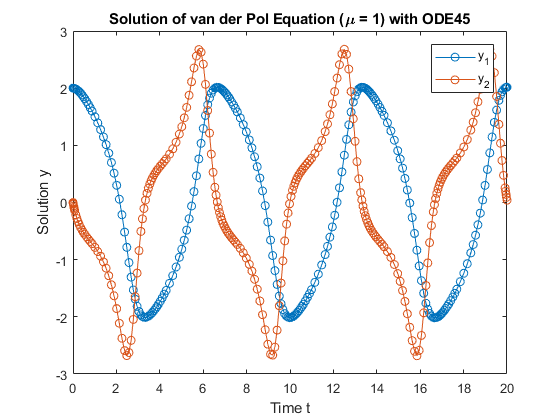

plot(t,y(:,1),'-o',t,y(:,2),'-o')
title('Solution of van der Pol Equation (\mu = 1) with ODE45');
xlabel('Time t');
ylabel('Solution y');
legend('y_1','y_2')